# Statistical Analysis for Lipid Data (WT vs KO)

This script analyzes lipid data, selecting the appropriate statistical test (parametric or nonparametric) based on data normality and variance. It also includes a Gaussian distribution test for normality and records the W-statistic from the Shapiro-Wilk test.

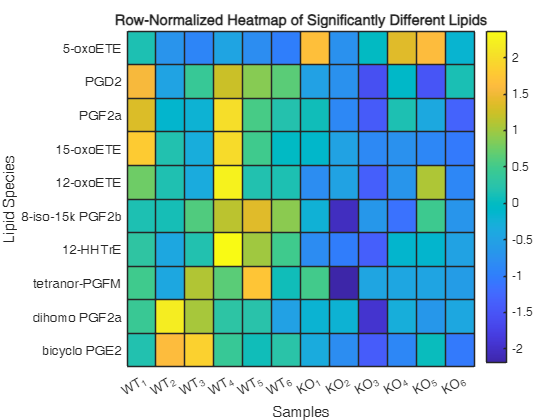

% Load the dataset
filename = 'LipidMapsInvData.xlsx';
sheet = 'LipidMapsSD data';
data = readtable(filename, 'Sheet', sheet);

% Extract lipid species names and group data
lipids = data{:, 1}; % First column: lipid names
WT_data = data{:, 2:7}; % WT columns (Wt_1 to Wt_6)
KO_data = data{:, 8:13}; % KO columns (KO_1 to KO_6)

% Initialize results table

results = table(lipids, cell(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), NaN(size(lipids)), NaN(size(lipids)), ...
    'VariableNames', ...
    {'Lipid', 'TestType', 'PValue', 'NormalityWT', 'NormalityKO', ...
     'GaussianWT', 'GaussianKO', 'ShapiroW_WT', 'ShapiroW_KO', 'FoldChange'});



% Loop through each lipid species
for i = 1:length(lipids)
    wt = WT_data(i, :); % WT replicates for this lipid
    ko = KO_data(i, :); % KO replicates for this lipid

     % Calculate means and fold change
    wt_mean = mean(wt);
    ko_mean = mean(ko);
    fold_change = ko_mean / wt_mean;

    % Remove NaN values
    wt = wt(~isnan(wt));
    ko = ko(~isnan(ko));

    % Test normality using Shapiro-Wilk test
    [h_wt, p_wt, w_stat_wt] = swtest(wt); % WT group
    [h_ko, p_ko, w_stat_ko] = swtest(ko); % KO group

    % Test normality against Gaussian distribution (KS test)
    [~, g_wt] = kstest((wt - mean(wt)) / std(wt)); % WT Gaussian test
    [~, g_ko] = kstest((ko - mean(ko)) / std(ko)); % KO Gaussian test

    % Store normality results
    results.NormalityWT(i) = p_wt; % Shapiro-Wilk p-value for WT
    results.NormalityKO(i) = p_ko; % Shapiro-Wilk p-value for KO
    results.ShapiroW_WT(i) = w_stat_wt; % Shapiro-Wilk W-statistic for WT
    results.ShapiroW_KO(i) = w_stat_ko; % Shapiro-Wilk W-statistic for KO
    results.GaussianWT(i) = g_wt; % KS test p-value for WT
    results.GaussianKO(i) = g_ko; % KS test p-value for KO

    % Determine test type (normality + variance equality)
    if p_wt > 0.05 && p_ko > 0.05 % Both groups are normal
        % Use Welch's t-test regardless of variance equality
        test_type = 'Welch''s t-test';
        [~, p] = ttest2(wt, ko, 'Vartype', 'unequal');
    else % Non-normal data
        test_type = 'Mann-Whitney U';
        p = ranksum(wt, ko);
    end

    % Store results
    results.TestType{i} = test_type; % Assign to cell array
    results.PValue(i) = p;
    results.PValue(i) = p;
    results.FoldChange(i) = fold_change; % Store fold change
end

% Filter significantly different lipids
significant_results = results(results.PValue < 0.05, :);

% Sort significant results by fold change (descending for upregulated, ascending for downregulated)
[~, sort_indices] = sort(significant_results.FoldChange, 'descend');
significant_results = significant_results(sort_indices, :);

% Create a row-normalized heatmap for significantly different lipids
if ~isempty(significant_results)
    % Extract concentration data for heatmap
    significant_indices = find(results.PValue < 0.05);
    heatmap_data = [WT_data(significant_indices, :) KO_data(significant_indices, :)];
    heatmap_data = heatmap_data(sort_indices, :); % Reorder heatmap data
    heatmap_data = normalize(heatmap_data, 2); % Row-normalize

    % Generate heatmap
    figure;
    heatmap_labels = ["WT_1", "WT_2", "WT_3", "WT_4", "WT_5", "WT_6", ...
                      "KO_1", "KO_2", "KO_3", "KO_4", "KO_5", "KO_6"];
    heatmap(heatmap_labels, significant_results.Lipid, heatmap_data, ...
            'Colormap', parula, 'ColorbarVisible', 'on');
    title('Row-Normalized Heatmap of Significantly Different Lipids');
    xlabel('Samples');
    ylabel('Lipid Species');
end




% Save results to a new Excel file
output_filename = 'LipidStatsResultsMa2025.xlsx';
writetable(results, output_filename);

% Display completion message
fprintf('Statistical analysis complete. Results saved to %s.\n', output_filename);

Statistical analysis complete. Results saved to LipidStatsResultsMa2025.xlsx.
